Curve Fitting - approximating polynomial equations for our data; lines of best fits

figure
hold on


Original Plot

x = 1:11;
y = [1 10 3 2.75 4.5 3.5 6 5.2 .75 6.3 5];
plot(x,y,'r.', 'markersize', 24)
axis([0 12 0 12])
title('Curve fitting to data points')
xlabel('x-axis')
ylabel('y-axis')


polyfit() and polyval()

polyfit - fits a polynomial to your data, outputs coefficient vector

- 2x^2 + 3x + 5 --> [2 3 5]

- 4x^3 + 2x -7 --> [4 0 2 -7]

- 4x^2 + 2x -7 --> [4 2 -7]

- length of ceoff = order + 1

coeff = polyfit(x, y, 2)

coeff =     0.0080   -0.0517    4.3067


polyval plugs in values to the polynomial

newx = linspace(1,11,500);

%First order curve fitting
coeff = polyfit(x, y, 1);
newy = polyval(coeff, newx);
plot(newx,newy,'g.', 'markersize', 5)

%Second order curve fitting
coeff = polyfit(x, y, 2);
newy = polyval(coeff, newx);
plot(newx,newy,'b.', 'markersize', 5)

%Third order curve fitting
coeff = polyfit(x, y, 3);
newy = polyval(coeff, newx);
plot(newx,newy,'m.', 'markersize', 5)

%Fourth order curve fitting
coeff = polyfit(x, y, 4);
newy = polyval(coeff, newx);
plot(newx,newy,'c.', 'markersize', 5)

%Tenth order curve fitting
coeff = polyfit(x, y, 10);

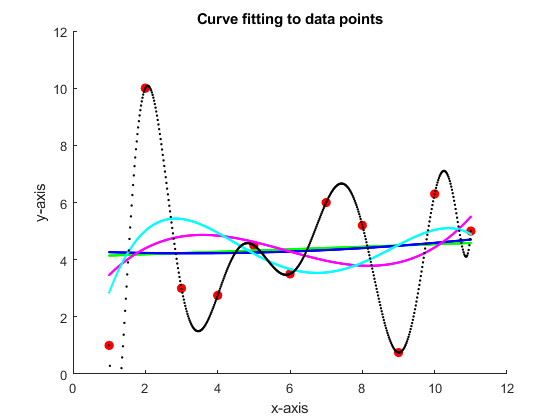

newy = polyval(coeff, newx);
plot(newx,newy,'k.', 'markersize', 5)